# P1

close all
clear
clc

Labels=["Dove" "Hen" "Duck" "Goose" "Owl" "Hawk" "Eagle" "Fox" "Dog" "Wolf" "Cat" "Tiger" "Lion" "Horse" "Zebra" "Cow" "Bear"]; 
Traits=["small" "medium" "large" "2 legs" "4 legs" "hair" "hooves" "mane" "feathers" "hunt" "run" "fly" "swim"];

L=numel(Labels);
Features=[1 1 1 1 0 1 0 0 0 0 1 0 0 0 0 0 0 
          0 0 0 0 1 0 1 1 1 1 0 0 0 0 0 0 0
          0 0 0 0 0 0 0 0 0 0 0 1 1 1 1 1 1
          1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0
          0 0 0 0 0 0 0 1 1 1 1 1 1 1 1 1 1
          0 0 0 0 0 0 0 1 1 1 1 1 1 1 1 1 1
          0 0 0 0 0 0 0 0 0 0 0 0 0 1 1 1 0
          0 0 0 0 0 0 0 0 0 1 0 0 1 1 1 0 0
          1 1 1 1 1 1 1 0 0 0 0 0 0 0 0 0 0
          0 0 0 0 1 1 1 1 0 1 1 1 1 0 0 0 1
          0 0 0 0 0 0 0 0 1 1 0 1 1 1 1 0 1
          1 0 0 1 1 1 1 0 0 0 0 0 0 0 0 0 0
          0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 0 1];
HotCode=diag(ones(1,L));
X=[HotCode;Features]';

Data=som_data_struct(X,'labels',cellstr(Labels'),'comp_names',cellstr([Labels Traits]'));
sMap=som_randinit(Data,'munits',169,'msize',[13 13],'lattice','hexa');
sMap=som_seqtrain(sMap,Data,'radius',3,'neigh','bubble','trainlen',1000,'alpha',0.3);

Training:   1/   1 s



som_show(sMap,'umat','all','size',10)
figure,
som_show(sMap,'comp',1:17)
u=som_umat(sMap);
u=u(1:2:end,1:2:end);
figure,
imagesc(u)
csvwrite('out.csv',[u(:) sMap.codebook])


# P2

close all
clear
clc

Labels=["1" "2" "3" "4" "5" "6" "7" "8" "9" "10" "11" "12" "13" "14" "15" "16" "17" "18" "19" "20" "21" "22" "23" "24" "25" "26" "27" "28"]; 
Traits=["D1" "D2" "D3" "T" "TT" "Years" "AOE" "Productivity" "P19" "P17" "Grant" "Writes"];

L=numel(Labels);
Features=[1 0 0 0 1 4  1 1 0 0 1  1
          0 0 1 0 1 1  0 0 0 0 0  0
          1	0 0	1 0	17 1 1 0 0 1 -1
          0	0 1	0 1	6  0 0 1 1 0 -1
          1	0 0	1 0	4  0 0 1 1 1  1
          0	1 0	0 1	4  1 1 1 1 0  1
          0	1 0	0 1	3  0 0 1 1 1  1
          0	0 1	0 1	1  0 0 0 0 0  0
          1	0 0	1 0	18 0 1 0 0 1 -1
          1	0 0	1 0	10 0 0 0 1 1  1
          0	0 1	0 1	3  0 1 1 0 0 -1
          0	1 0	0 1	0  1 1 0 1 0  0
          0	0 1	0 1	5  0 0 1 1 1 -1
          0	1 0	0 1	0  0 0 0 1 0  0
          1	0 0	1 0	7  1 1 1 1 1  1
          1	0 0	0 1	4  1 1 0 0 1 -1
          0	0 1	0 1	2  0 1 1 0 1 -1
          1	0 0	1 0	11 0 0 1 0 1  0
          1	0 0	0 1	1  0 0 0 0 0  0
          0	0 1	1 0	11 0 1 1 1 1 -1
          0	1 0	1 0	14 0 0 0 0 1  0
          0	0 1	0 1	3  0 1 1 1 1  1
          1	0 0	0 1	1  0 0 0 0 0  0
          1	0 0	0 1	0  1 1 1 1 0  1
          0	0 1	1 0	10 1 1 1 0 1 -1
          1	0 0	1 0	6  1 1 0 1 1  0
          0	1 0	0 1	3  0 0 0 1 1  1
          1	0 0	1 0	13 1 1 0 0 1 -1];
      
Features=Features-repmat(min(Features),size(Features,1),1);      
Features=Features./repmat(max(Features),size(Features,1),1);      
HotCode=diag(ones(1,L));
X=[HotCode,Features];

Data=som_data_struct(X,'labels',cellstr(Labels'),'comp_names',cellstr([Labels Traits]'));
sMap=som_randinit(Data,'munits',169,'msize',[15 15],'lattice','hexa');
sMap=som_seqtrain(sMap,Data,'radius',3,'neigh','bubble','trainlen',1000,'alpha',0.3);

Training:   4/   4 s


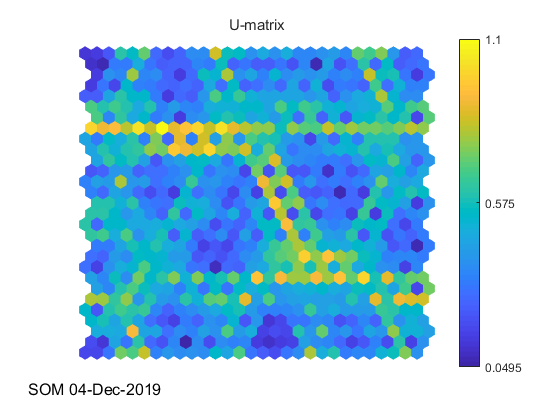


som_show(sMap,'umat','all','size',10)

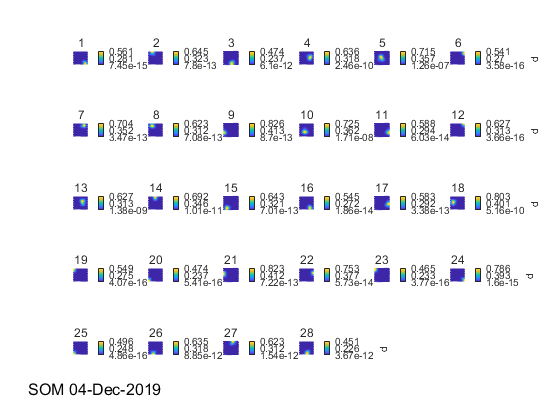

figure,
som_show(sMap,'comp',1:28)

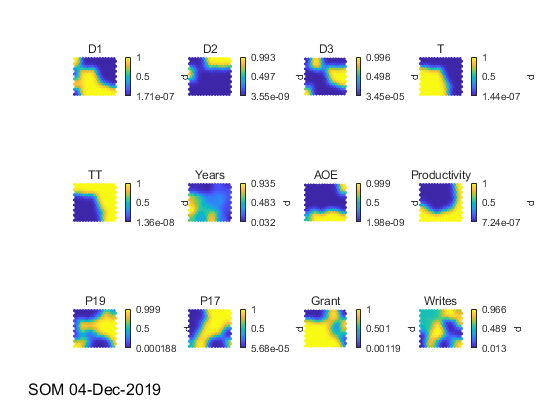

figure,
som_show(sMap,'comp',29:40)

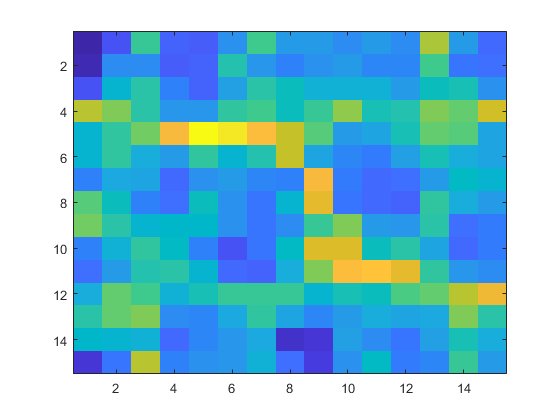

u=som_umat(sMap);
u=u(1:2:end,1:2:end);
figure,
imagesc(u)

csvwrite('out2.csv',[u(:) sMap.codebook])

